clear

load('data/Sensitivity_100Hz.mat')
lim = 20e-3;

mask = -lim < element_centers(1,:) &  element_centers(1,:) < lim & ...
       -lim < element_centers(2,:) &  element_centers(2,:) < lim;

S = S(:, mask);
element_centers = element_centers(:, mask);

lambda = 1e-26;
R = (S' * S + lambda * eye(size(S,2))) \ S';

B0 = readmatrix('data/B_defectless.txt');
B0 = B0(:, 2:end);

B = readmatrix('data/B_defect.txt');
B = B(:, 2:end);

delta_B = B - B0;
delta_B = delta_B(3,:);

delta_sigma = R * delta_B(:);

clear B0 B delta_B

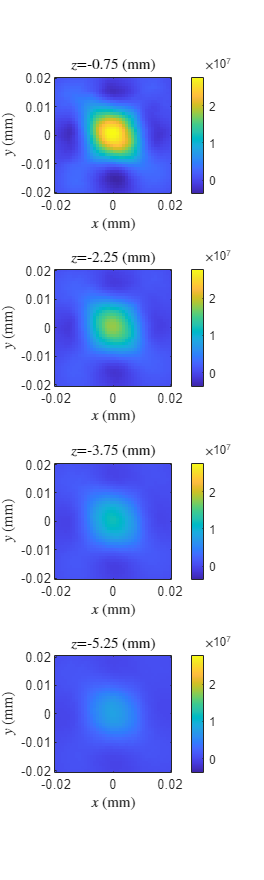

z = unique(element_centers(3,:));
z = sort(z, 'descend');

c = real(-delta_sigma);

figure('Position',[10 10 300 250*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    subplot(length(z),1,k)
    imagesc([-lim lim],[-lim lim], c_layer.', [min(c) max(c)])
    colorbar
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end


clear lim mask k z c c_layer